# 1D Kalman Filtering

***This is a First-Order or Two-State Filter recursive approach***


$$\hat x_k=a_0+a_1(k-1)T_s$$



$$\[{x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t\]$$


This example follows the Lecture note: 

Understanding the Basis of the Kalman Filter Via a Simple and Intuitive Derivation.

Find it in the folder: ... /MatlabDrive/Robotica_20_21_2Q/11_Localization

## Problem statement

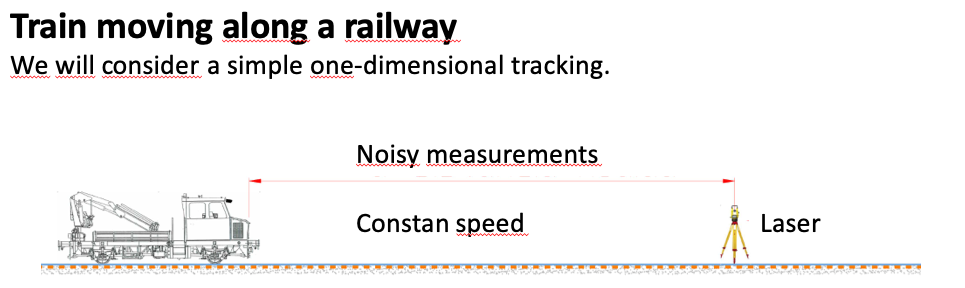

**The problem:** Predict the position and velocity of a moving  train 2 seconds ahead, having noisy measurements of its positions along the previous 10 seconds (10 samples a second)

The train is initially located at the point $x=0$ and moves along the $\hat X$ axis with constant velocity $\dot x=10 m/s$, so the motion equation of the train is: $\[{x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t\]$. Easy to see that the position of the train after 12 seconds will be x = 120m, and this is what we will try to find.

**Approach:** We measure (sample) the position of the train every $\Delta t=0.1[s]$ But, because of imperfect apparature, weather etc., our measurements are noisy, so the instantaneous velocity, derived from 2 consecutive position measurements, (remember, we measure only position) is innacurate. We will use Kalman filter as we need an accurate and smooth estimate for the velocity in order to predict train's position in the future.

We assume that the measurement noise is normally distributed $N(\mu,\sigma)$

clear

## Theoric Position 

Xtrue is a vector of true positions of the train 

Nsamples=400;
dt = 0.1;
t=0:dt:dt*Nsamples;
Vtrue = 10;
Xinitial = 0;
Xtrue = Xinitial + Vtrue * t;

## Motion equation


$${x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t\\ \dot x_k=\dot x_{k-1}$$


In matrix form


$$\left( {\begin{array}{*{20}{c}}
  {{x_k}} \\ 
  {{{\dot x}_k}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  1&{\Delta t} \\ 
  0&1 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  {{x_{k - 1}}} \\ 
  {{{\dot x}_{k - 1}}} 
\end{array}} \right) \to X_k= \Phi X_{k-1}$$


Xk = Phi*Xk_prev + Noise, that is Xk(n) = Xk(n-1) + Vk(n-1) * dt + Noise

Of course, velocity, ($\dot x$) is not measured, but it is estimated.  Phi ($\Phi$) represents the dynamics of the system: it is the motion equation.

Phi = [1 dt;
       0  1];

### Previous state 

Our initial guess is that the train starts at 0 with velocity that equals to 50% of the real velocity

Xk_prev = [0; 0.5*Vtrue];

### Current state estimate

Xk=[];

## Definitions 

### Error matrix 

Also confidence matrix. P states whether we should give more weight to the new measurement or to the model estimate.

sigma_model = 1;
P = [sigma_model^2 0;
     0 sigma_model^2];

### Process noise

Q is the process noise covariance. It represents the amount of uncertainty in the model. In our case, we arbitrarily assume that the model is perfect (no acceleration allowed for the train, or in other words - any acceleration is considered to be a noise)

Q = [0.01 0;
     0 0.1];

### Measurement matrix. 

M is the measurement matrix. We measure X, [1 0] .  We do not measure velocity (V), so M(2)= 0

H = [1 0];

### Measurement noise covariance

 R is the measurement noise covariance. Generally R and sigma_meas can vary between samples. 

sigma_meas = 2; % 2 m
R = sigma_meas^2;

## Kalman iteration

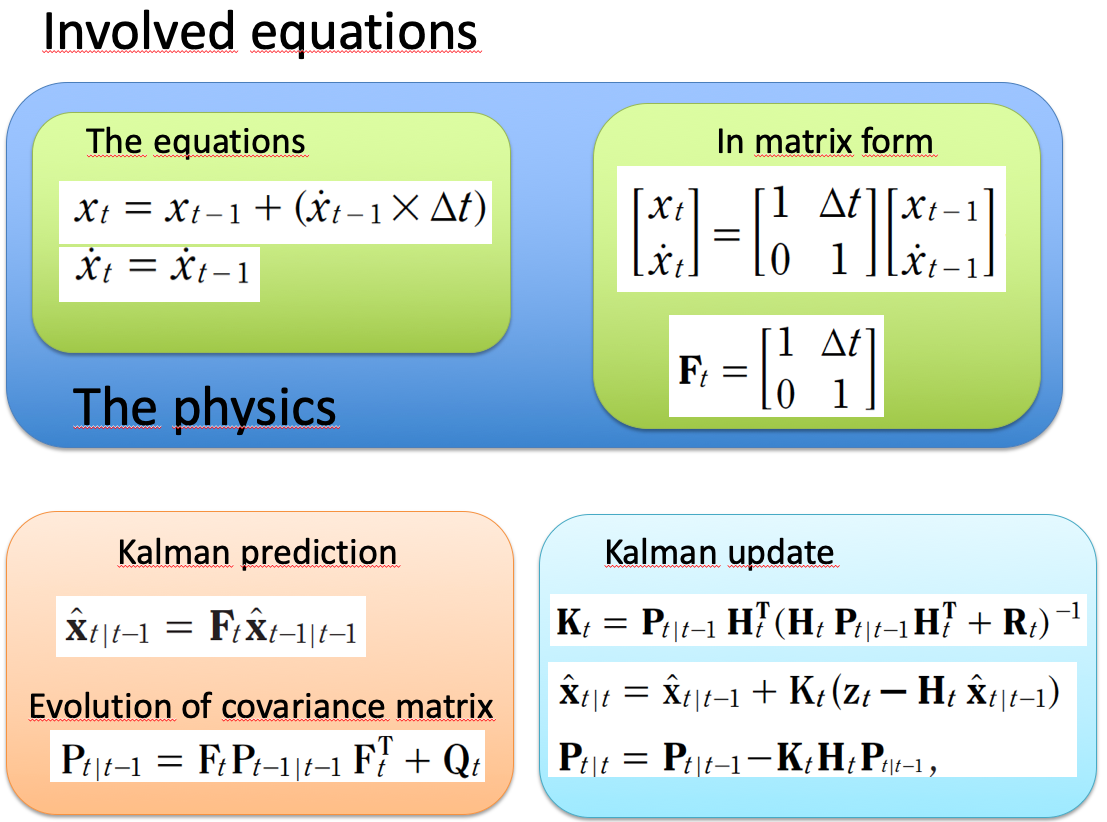

Buffers for later display

Xk_buffer = zeros(2,Nsamples+1);
Xk_buffer(:,1) = Xk_prev;
Z_buffer = zeros(1,Nsamples+1);
K_buffer = zeros(2,Nsamples+1);

## The iterative kalman filtering

Z is the measurement vector. In our case, Z = TrueData + RandomGaussianNoise

Y_N=1; % 1:Yes we use the laser; 0 otherwise
Laser_Rate=5; %Every N sampled Laser distance is avalaible
Kalman_Data=estimate_update(Y_N,Laser_Rate,Nsamples,Xk_prev,Xinitial);% first: y/n update, second when... every ...

Xtrue = 5

Kalman = struct with fields:
    Xk: [2×6 double]
    P1: [2×2×5 double]
     Z: [0 0 0 0 0 5.9285]
     K: [2×6 double]
     P: [2×2×6 double]

Kalman = struct with fields:
    Xk: [2×6 double]
    P1: [2×2×6 double]
     Z: [0 0 0 0 0 5.9285]
     K: [2×6 double]
     P: [2×2×6 double]

Xtrue = 10

Kalman = struct with fields:
    Xk: [2×11 double]
    P1: [2×2×10 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855]
     K: [2×11 double]
     P: [2×2×11 double]

Kalman = struct with fields:
    Xk: [2×11 double]
    P1: [2×2×11 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855]
     K: [2×11 double]
     P: [2×2×11 double]

Xtrue = 15

Kalman = struct with fields:
    Xk: [2×16 double]
    P1: [2×2×15 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195]
     K: [2×16 double]
     P: [2×2×16 double]

Kalman = struct with fields:
    Xk: [2×16 double]
    P1: [2×2×16 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195]
     K: [2×16 double]
     P: [2×2×16 double]

Xtrue = 20

Kalman = struct with fields:
    Xk: [2×21 double]
    P1: [2×2×20 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531]
     K: [2×21 double]
     P: [2×2×21 double]

Kalman = struct with fields:
    Xk: [2×21 double]
    P1: [2×2×21 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531]
     K: [2×21 double]
     P: [2×2×21 double]

Xtrue = 25

Kalman = struct with fields:
    Xk: [2×26 double]
    P1: [2×2×25 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587]
     K: [2×26 double]
     P: [2×2×26 double]

Kalman = struct with fields:
    Xk: [2×26 double]
    P1: [2×2×26 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587]
     K: [2×26 double]
     P: [2×2×26 double]

Xtrue = 30

Kalman = struct with fields:
    Xk: [2×31 double]
    P1: [2×2×30 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753]
     K: [2×31 double]
     P: [2×2×31 double]

Kalman = struct with fields:
    Xk: [2×31 double]
    P1: [2×2×31 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753]
     K: [2×31 double]
     P: [2×2×31 double]

Xtrue = 35

Kalman = struct with fields:
    Xk: [2×36 double]
    P1: [2×2×35 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597]
     K: [2×36 double]
     P: [2×2×36 double]

Kalman = struct with fields:
    Xk: [2×36 double]
    P1: [2×2×36 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597]
     K: [2×36 double]
     P: [2×2×36 double]

Xtrue = 40

Kalman = struct with fields:
    Xk: [2×41 double]
    P1: [2×2×40 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601]
     K: [2×41 double]
     P: [2×2×41 double]

Kalman = struct with fields:
    Xk: [2×41 double]
    P1: [2×2×41 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601]
     K: [2×41 double]
     P: [2×2×41 double]

Xtrue = 45

Kalman = struct with fields:
    Xk: [2×46 double]
    P1: [2×2×45 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194]
     K: [2×46 double]
     P: [2×2×46 double]

Kalman = struct with fields:
    Xk: [2×46 double]
    P1: [2×2×46 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194]
     K: [2×46 double]
     P: [2×2×46 double]

Xtrue = 50

Kalman = struct with fields:
    Xk: [2×51 double]
    P1: [2×2×50 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449]
     K: [2×51 double]
     P: [2×2×51 double]

Kalman = struct with fields:
    Xk: [2×51 double]
    P1: [2×2×51 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449]
     K: [2×51 double]
     P: [2×2×51 double]

Xtrue = 55

Kalman = struct with fields:
    Xk: [2×56 double]
    P1: [2×2×55 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749]
     K: [2×56 double]
     P: [2×2×56 double]

Kalman = struct with fields:
    Xk: [2×56 double]
    P1: [2×2×56 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749]
     K: [2×56 double]
     P: [2×2×56 double]

Xtrue = 60

Kalman = struct with fields:
    Xk: [2×61 double]
    P1: [2×2×60 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197]
     K: [2×61 double]
     P: [2×2×61 double]

Kalman = struct with fields:
    Xk: [2×61 double]
    P1: [2×2×61 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197]
     K: [2×61 double]
     P: [2×2×61 double]

Xtrue = 65

Kalman = struct with fields:
    Xk: [2×66 double]
    P1: [2×2×65 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197 0 0 0 0 68.2174]
     K: [2×66 double]
     P: [2×2×66 double]

Kalman = struct with fields:
    Xk: [2×66 double]
    P1: [2×2×66 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197 0 0 0 0 68.2174]
     K: [2×66 double]
     P: [2×2×66 double]

Xtrue = 70

Kalman = struct with fields:
    Xk: [2×71 double]
    P1: [2×2×70 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197 0 0 0 0 68.2174 0 0 0 0 68.5549]
     K: [2×71 double]
     P: [2×2×71 double]

Kalman = struct with fields:
    Xk: [2×71 double]
    P1: [2×2×71 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197 0 0 0 0 68.2174 0 0 0 0 68.5549]
     K: [2×71 double]
     P: [2×2×71 double]

Xtrue = 75

Kalman = struct with fields:
    Xk: [2×76 double]
    P1: [2×2×75 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197 0 0 0 0 68.2174 0 0 0 0 68.5549 0 0 0 0 77.5839]
     K: [2×76 double]
     P: [2×2×76 double]

Kalman = struct with fields:
    Xk: [2×76 double]
    P1: [2×2×76 double]
     Z: [0 0 0 0 0 5.9285 0 0 0 0 12.2855 0 0 0 0 15.4195 0 0 0 0 20.3531 0 0 0 0 24.6587 0 0 0 0 28.6753 0 0 0 0 31.8597 0 0 0 0 39.0601 0 0 0 0 46.5194 0 0 0 0 49.2449 0 0 0 0 56.7749 0 0 0 0 56.7197 0 0 0 0 68.2174 0 0 0 0 68.5549 0 0 0 0 77.5839]
     K: [2×76 double]
     P: [2×2×76 double]

Xtrue = 80

Kalman = struct with fields:
    Xk: [2×81 double]
    P1: [2×2×80 double]
     Z: [1×81 double]
     K: [2×81 double]
     P: [2×2×81 double]

Kalman = struct with fields:
    Xk: [2×81 double]
    P1: [2×2×81 double]
     Z: [1×81 double]
     K: [2×81 double]
     P: [2×2×81 double]

Xtrue = 85

Kalman = struct with fields:
    Xk: [2×86 double]
    P1: [2×2×85 double]
     Z: [1×86 double]
     K: [2×86 double]
     P: [2×2×86 double]

Kalman = struct with fields:
    Xk: [2×86 double]
    P1: [2×2×86 double]
     Z: [1×86 double]
     K: [2×86 double]
     P: [2×2×86 double]

Xtrue = 90

Kalman = struct with fields:
    Xk: [2×91 double]
    P1: [2×2×90 double]
     Z: [1×91 double]
     K: [2×91 double]
     P: [2×2×91 double]

Kalman = struct with fields:
    Xk: [2×91 double]
    P1: [2×2×91 double]
     Z: [1×91 double]
     K: [2×91 double]
     P: [2×2×91 double]

Xtrue = 95

Kalman = struct with fields:
    Xk: [2×96 double]
    P1: [2×2×95 double]
     Z: [1×96 double]
     K: [2×96 double]
     P: [2×2×96 double]

Kalman = struct with fields:
    Xk: [2×96 double]
    P1: [2×2×96 double]
     Z: [1×96 double]
     K: [2×96 double]
     P: [2×2×96 double]

Xtrue = 100

Kalman = struct with fields:
    Xk: [2×101 double]
    P1: [2×2×100 double]
     Z: [1×101 double]
     K: [2×101 double]
     P: [2×2×101 double]

Kalman = struct with fields:
    Xk: [2×101 double]
    P1: [2×2×101 double]
     Z: [1×101 double]
     K: [2×101 double]
     P: [2×2×101 double]

Xtrue = 105

Kalman = struct with fields:
    Xk: [2×106 double]
    P1: [2×2×105 double]
     Z: [1×106 double]
     K: [2×106 double]
     P: [2×2×106 double]

Kalman = struct with fields:
    Xk: [2×106 double]
    P1: [2×2×106 double]
     Z: [1×106 double]
     K: [2×106 double]
     P: [2×2×106 double]

Xtrue = 110

Kalman = struct with fields:
    Xk: [2×111 double]
    P1: [2×2×110 double]
     Z: [1×111 double]
     K: [2×111 double]
     P: [2×2×111 double]

Kalman = struct with fields:
    Xk: [2×111 double]
    P1: [2×2×111 double]
     Z: [1×111 double]
     K: [2×111 double]
     P: [2×2×111 double]

Xtrue = 115

Kalman = struct with fields:
    Xk: [2×116 double]
    P1: [2×2×115 double]
     Z: [1×116 double]
     K: [2×116 double]
     P: [2×2×116 double]

Kalman = struct with fields:
    Xk: [2×116 double]
    P1: [2×2×116 double]
     Z: [1×116 double]
     K: [2×116 double]
     P: [2×2×116 double]

Xtrue = 120

Kalman = struct with fields:
    Xk: [2×121 double]
    P1: [2×2×120 double]
     Z: [1×121 double]
     K: [2×121 double]
     P: [2×2×121 double]

Kalman = struct with fields:
    Xk: [2×121 double]
    P1: [2×2×121 double]
     Z: [1×121 double]
     K: [2×121 double]
     P: [2×2×121 double]

Xtrue = 125

Kalman = struct with fields:
    Xk: [2×126 double]
    P1: [2×2×125 double]
     Z: [1×126 double]
     K: [2×126 double]
     P: [2×2×126 double]

Kalman = struct with fields:
    Xk: [2×126 double]
    P1: [2×2×126 double]
     Z: [1×126 double]
     K: [2×126 double]
     P: [2×2×126 double]

Xtrue = 130

Kalman = struct with fields:
    Xk: [2×131 double]
    P1: [2×2×130 double]
     Z: [1×131 double]
     K: [2×131 double]
     P: [2×2×131 double]

Kalman = struct with fields:
    Xk: [2×131 double]
    P1: [2×2×131 double]
     Z: [1×131 double]
     K: [2×131 double]
     P: [2×2×131 double]

Xtrue = 135

Kalman = struct with fields:
    Xk: [2×136 double]
    P1: [2×2×135 double]
     Z: [1×136 double]
     K: [2×136 double]
     P: [2×2×136 double]

Kalman = struct with fields:
    Xk: [2×136 double]
    P1: [2×2×136 double]
     Z: [1×136 double]
     K: [2×136 double]
     P: [2×2×136 double]

Xtrue = 140

Kalman = struct with fields:
    Xk: [2×141 double]
    P1: [2×2×140 double]
     Z: [1×141 double]
     K: [2×141 double]
     P: [2×2×141 double]

Kalman = struct with fields:
    Xk: [2×141 double]
    P1: [2×2×141 double]
     Z: [1×141 double]
     K: [2×141 double]
     P: [2×2×141 double]

Xtrue = 145

Kalman = struct with fields:
    Xk: [2×146 double]
    P1: [2×2×145 double]
     Z: [1×146 double]
     K: [2×146 double]
     P: [2×2×146 double]

Kalman = struct with fields:
    Xk: [2×146 double]
    P1: [2×2×146 double]
     Z: [1×146 double]
     K: [2×146 double]
     P: [2×2×146 double]

Xtrue = 150

Kalman = struct with fields:
    Xk: [2×151 double]
    P1: [2×2×150 double]
     Z: [1×151 double]
     K: [2×151 double]
     P: [2×2×151 double]

Kalman = struct with fields:
    Xk: [2×151 double]
    P1: [2×2×151 double]
     Z: [1×151 double]
     K: [2×151 double]
     P: [2×2×151 double]

Xtrue = 155

Kalman = struct with fields:
    Xk: [2×156 double]
    P1: [2×2×155 double]
     Z: [1×156 double]
     K: [2×156 double]
     P: [2×2×156 double]

Kalman = struct with fields:
    Xk: [2×156 double]
    P1: [2×2×156 double]
     Z: [1×156 double]
     K: [2×156 double]
     P: [2×2×156 double]

Xtrue = 160

Kalman = struct with fields:
    Xk: [2×161 double]
    P1: [2×2×160 double]
     Z: [1×161 double]
     K: [2×161 double]
     P: [2×2×161 double]

Kalman = struct with fields:
    Xk: [2×161 double]
    P1: [2×2×161 double]
     Z: [1×161 double]
     K: [2×161 double]
     P: [2×2×161 double]

Xtrue = 165

Kalman = struct with fields:
    Xk: [2×166 double]
    P1: [2×2×165 double]
     Z: [1×166 double]
     K: [2×166 double]
     P: [2×2×166 double]

Kalman = struct with fields:
    Xk: [2×166 double]
    P1: [2×2×166 double]
     Z: [1×166 double]
     K: [2×166 double]
     P: [2×2×166 double]

Xtrue = 170

Kalman = struct with fields:
    Xk: [2×171 double]
    P1: [2×2×170 double]
     Z: [1×171 double]
     K: [2×171 double]
     P: [2×2×171 double]

Kalman = struct with fields:
    Xk: [2×171 double]
    P1: [2×2×171 double]
     Z: [1×171 double]
     K: [2×171 double]
     P: [2×2×171 double]

Xtrue = 175

Kalman = struct with fields:
    Xk: [2×176 double]
    P1: [2×2×175 double]
     Z: [1×176 double]
     K: [2×176 double]
     P: [2×2×176 double]

Kalman = struct with fields:
    Xk: [2×176 double]
    P1: [2×2×176 double]
     Z: [1×176 double]
     K: [2×176 double]
     P: [2×2×176 double]

Xtrue = 180

Kalman = struct with fields:
    Xk: [2×181 double]
    P1: [2×2×180 double]
     Z: [1×181 double]
     K: [2×181 double]
     P: [2×2×181 double]

Kalman = struct with fields:
    Xk: [2×181 double]
    P1: [2×2×181 double]
     Z: [1×181 double]
     K: [2×181 double]
     P: [2×2×181 double]

Xtrue = 185

Kalman = struct with fields:
    Xk: [2×186 double]
    P1: [2×2×185 double]
     Z: [1×186 double]
     K: [2×186 double]
     P: [2×2×186 double]

Kalman = struct with fields:
    Xk: [2×186 double]
    P1: [2×2×186 double]
     Z: [1×186 double]
     K: [2×186 double]
     P: [2×2×186 double]

Xtrue = 190

Kalman = struct with fields:
    Xk: [2×191 double]
    P1: [2×2×190 double]
     Z: [1×191 double]
     K: [2×191 double]
     P: [2×2×191 double]

Kalman = struct with fields:
    Xk: [2×191 double]
    P1: [2×2×191 double]
     Z: [1×191 double]
     K: [2×191 double]
     P: [2×2×191 double]

Xtrue = 195

Kalman = struct with fields:
    Xk: [2×196 double]
    P1: [2×2×195 double]
     Z: [1×196 double]
     K: [2×196 double]
     P: [2×2×196 double]

Kalman = struct with fields:
    Xk: [2×196 double]
    P1: [2×2×196 double]
     Z: [1×196 double]
     K: [2×196 double]
     P: [2×2×196 double]

Xtrue = 200

Kalman = struct with fields:
    Xk: [2×201 double]
    P1: [2×2×200 double]
     Z: [1×201 double]
     K: [2×201 double]
     P: [2×2×201 double]

Kalman = struct with fields:
    Xk: [2×201 double]
    P1: [2×2×201 double]
     Z: [1×201 double]
     K: [2×201 double]
     P: [2×2×201 double]

Xtrue = 205

Kalman = struct with fields:
    Xk: [2×206 double]
    P1: [2×2×205 double]
     Z: [1×206 double]
     K: [2×206 double]
     P: [2×2×206 double]

Kalman = struct with fields:
    Xk: [2×206 double]
    P1: [2×2×206 double]
     Z: [1×206 double]
     K: [2×206 double]
     P: [2×2×206 double]

Xtrue = 210

Kalman = struct with fields:
    Xk: [2×211 double]
    P1: [2×2×210 double]
     Z: [1×211 double]
     K: [2×211 double]
     P: [2×2×211 double]

Kalman = struct with fields:
    Xk: [2×211 double]
    P1: [2×2×211 double]
     Z: [1×211 double]
     K: [2×211 double]
     P: [2×2×211 double]

Xtrue = 215

Kalman = struct with fields:
    Xk: [2×216 double]
    P1: [2×2×215 double]
     Z: [1×216 double]
     K: [2×216 double]
     P: [2×2×216 double]

Kalman = struct with fields:
    Xk: [2×216 double]
    P1: [2×2×216 double]
     Z: [1×216 double]
     K: [2×216 double]
     P: [2×2×216 double]

Xtrue = 220

Kalman = struct with fields:
    Xk: [2×221 double]
    P1: [2×2×220 double]
     Z: [1×221 double]
     K: [2×221 double]
     P: [2×2×221 double]

Kalman = struct with fields:
    Xk: [2×221 double]
    P1: [2×2×221 double]
     Z: [1×221 double]
     K: [2×221 double]
     P: [2×2×221 double]

Xtrue = 225

Kalman = struct with fields:
    Xk: [2×226 double]
    P1: [2×2×225 double]
     Z: [1×226 double]
     K: [2×226 double]
     P: [2×2×226 double]

Kalman = struct with fields:
    Xk: [2×226 double]
    P1: [2×2×226 double]
     Z: [1×226 double]
     K: [2×226 double]
     P: [2×2×226 double]

Xtrue = 230

Kalman = struct with fields:
    Xk: [2×231 double]
    P1: [2×2×230 double]
     Z: [1×231 double]
     K: [2×231 double]
     P: [2×2×231 double]

Kalman = struct with fields:
    Xk: [2×231 double]
    P1: [2×2×231 double]
     Z: [1×231 double]
     K: [2×231 double]
     P: [2×2×231 double]

Xtrue = 235

Kalman = struct with fields:
    Xk: [2×236 double]
    P1: [2×2×235 double]
     Z: [1×236 double]
     K: [2×236 double]
     P: [2×2×236 double]

Kalman = struct with fields:
    Xk: [2×236 double]
    P1: [2×2×236 double]
     Z: [1×236 double]
     K: [2×236 double]
     P: [2×2×236 double]

Xtrue = 240

Kalman = struct with fields:
    Xk: [2×241 double]
    P1: [2×2×240 double]
     Z: [1×241 double]
     K: [2×241 double]
     P: [2×2×241 double]

Kalman = struct with fields:
    Xk: [2×241 double]
    P1: [2×2×241 double]
     Z: [1×241 double]
     K: [2×241 double]
     P: [2×2×241 double]

Xtrue = 245

Kalman = struct with fields:
    Xk: [2×246 double]
    P1: [2×2×245 double]
     Z: [1×246 double]
     K: [2×246 double]
     P: [2×2×246 double]

Kalman = struct with fields:
    Xk: [2×246 double]
    P1: [2×2×246 double]
     Z: [1×246 double]
     K: [2×246 double]
     P: [2×2×246 double]

Xtrue = 250

Kalman = struct with fields:
    Xk: [2×251 double]
    P1: [2×2×250 double]
     Z: [1×251 double]
     K: [2×251 double]
     P: [2×2×251 double]

Kalman = struct with fields:
    Xk: [2×251 double]
    P1: [2×2×251 double]
     Z: [1×251 double]
     K: [2×251 double]
     P: [2×2×251 double]

Xtrue = 255

Kalman = struct with fields:
    Xk: [2×256 double]
    P1: [2×2×255 double]
     Z: [1×256 double]
     K: [2×256 double]
     P: [2×2×256 double]

Kalman = struct with fields:
    Xk: [2×256 double]
    P1: [2×2×256 double]
     Z: [1×256 double]
     K: [2×256 double]
     P: [2×2×256 double]

Xtrue = 260

Kalman = struct with fields:
    Xk: [2×261 double]
    P1: [2×2×260 double]
     Z: [1×261 double]
     K: [2×261 double]
     P: [2×2×261 double]

Kalman = struct with fields:
    Xk: [2×261 double]
    P1: [2×2×261 double]
     Z: [1×261 double]
     K: [2×261 double]
     P: [2×2×261 double]

Xtrue = 265

Kalman = struct with fields:
    Xk: [2×266 double]
    P1: [2×2×265 double]
     Z: [1×266 double]
     K: [2×266 double]
     P: [2×2×266 double]

Kalman = struct with fields:
    Xk: [2×266 double]
    P1: [2×2×266 double]
     Z: [1×266 double]
     K: [2×266 double]
     P: [2×2×266 double]

Xtrue = 270

Kalman = struct with fields:
    Xk: [2×271 double]
    P1: [2×2×270 double]
     Z: [1×271 double]
     K: [2×271 double]
     P: [2×2×271 double]

Kalman = struct with fields:
    Xk: [2×271 double]
    P1: [2×2×271 double]
     Z: [1×271 double]
     K: [2×271 double]
     P: [2×2×271 double]

Xtrue = 275

Kalman = struct with fields:
    Xk: [2×276 double]
    P1: [2×2×275 double]
     Z: [1×276 double]
     K: [2×276 double]
     P: [2×2×276 double]

Kalman = struct with fields:
    Xk: [2×276 double]
    P1: [2×2×276 double]
     Z: [1×276 double]
     K: [2×276 double]
     P: [2×2×276 double]

Xtrue = 280

Kalman = struct with fields:
    Xk: [2×281 double]
    P1: [2×2×280 double]
     Z: [1×281 double]
     K: [2×281 double]
     P: [2×2×281 double]

Kalman = struct with fields:
    Xk: [2×281 double]
    P1: [2×2×281 double]
     Z: [1×281 double]
     K: [2×281 double]
     P: [2×2×281 double]

Xtrue = 285

Kalman = struct with fields:
    Xk: [2×286 double]
    P1: [2×2×285 double]
     Z: [1×286 double]
     K: [2×286 double]
     P: [2×2×286 double]

Kalman = struct with fields:
    Xk: [2×286 double]
    P1: [2×2×286 double]
     Z: [1×286 double]
     K: [2×286 double]
     P: [2×2×286 double]

Xtrue = 290

Kalman = struct with fields:
    Xk: [2×291 double]
    P1: [2×2×290 double]
     Z: [1×291 double]
     K: [2×291 double]
     P: [2×2×291 double]

Kalman = struct with fields:
    Xk: [2×291 double]
    P1: [2×2×291 double]
     Z: [1×291 double]
     K: [2×291 double]
     P: [2×2×291 double]

Xtrue = 295

Kalman = struct with fields:
    Xk: [2×296 double]
    P1: [2×2×295 double]
     Z: [1×296 double]
     K: [2×296 double]
     P: [2×2×296 double]

Kalman = struct with fields:
    Xk: [2×296 double]
    P1: [2×2×296 double]
     Z: [1×296 double]
     K: [2×296 double]
     P: [2×2×296 double]

Xtrue = 300

Kalman = struct with fields:
    Xk: [2×301 double]
    P1: [2×2×300 double]
     Z: [1×301 double]
     K: [2×301 double]
     P: [2×2×301 double]

Kalman = struct with fields:
    Xk: [2×301 double]
    P1: [2×2×301 double]
     Z: [1×301 double]
     K: [2×301 double]
     P: [2×2×301 double]

Xtrue = 305

Kalman = struct with fields:
    Xk: [2×306 double]
    P1: [2×2×305 double]
     Z: [1×306 double]
     K: [2×306 double]
     P: [2×2×306 double]

Kalman = struct with fields:
    Xk: [2×306 double]
    P1: [2×2×306 double]
     Z: [1×306 double]
     K: [2×306 double]
     P: [2×2×306 double]

Xtrue = 310

Kalman = struct with fields:
    Xk: [2×311 double]
    P1: [2×2×310 double]
     Z: [1×311 double]
     K: [2×311 double]
     P: [2×2×311 double]

Kalman = struct with fields:
    Xk: [2×311 double]
    P1: [2×2×311 double]
     Z: [1×311 double]
     K: [2×311 double]
     P: [2×2×311 double]

Xtrue = 315

Kalman = struct with fields:
    Xk: [2×316 double]
    P1: [2×2×315 double]
     Z: [1×316 double]
     K: [2×316 double]
     P: [2×2×316 double]

Kalman = struct with fields:
    Xk: [2×316 double]
    P1: [2×2×316 double]
     Z: [1×316 double]
     K: [2×316 double]
     P: [2×2×316 double]

Xtrue = 320

Kalman = struct with fields:
    Xk: [2×321 double]
    P1: [2×2×320 double]
     Z: [1×321 double]
     K: [2×321 double]
     P: [2×2×321 double]

Kalman = struct with fields:
    Xk: [2×321 double]
    P1: [2×2×321 double]
     Z: [1×321 double]
     K: [2×321 double]
     P: [2×2×321 double]

Xtrue = 325

Kalman = struct with fields:
    Xk: [2×326 double]
    P1: [2×2×325 double]
     Z: [1×326 double]
     K: [2×326 double]
     P: [2×2×326 double]

Kalman = struct with fields:
    Xk: [2×326 double]
    P1: [2×2×326 double]
     Z: [1×326 double]
     K: [2×326 double]
     P: [2×2×326 double]

Xtrue = 330

Kalman = struct with fields:
    Xk: [2×331 double]
    P1: [2×2×330 double]
     Z: [1×331 double]
     K: [2×331 double]
     P: [2×2×331 double]

Kalman = struct with fields:
    Xk: [2×331 double]
    P1: [2×2×331 double]
     Z: [1×331 double]
     K: [2×331 double]
     P: [2×2×331 double]

Xtrue = 335

Kalman = struct with fields:
    Xk: [2×336 double]
    P1: [2×2×335 double]
     Z: [1×336 double]
     K: [2×336 double]
     P: [2×2×336 double]

Kalman = struct with fields:
    Xk: [2×336 double]
    P1: [2×2×336 double]
     Z: [1×336 double]
     K: [2×336 double]
     P: [2×2×336 double]

Xtrue = 340

Kalman = struct with fields:
    Xk: [2×341 double]
    P1: [2×2×340 double]
     Z: [1×341 double]
     K: [2×341 double]
     P: [2×2×341 double]

Kalman = struct with fields:
    Xk: [2×341 double]
    P1: [2×2×341 double]
     Z: [1×341 double]
     K: [2×341 double]
     P: [2×2×341 double]

Xtrue = 345

Kalman = struct with fields:
    Xk: [2×346 double]
    P1: [2×2×345 double]
     Z: [1×346 double]
     K: [2×346 double]
     P: [2×2×346 double]

Kalman = struct with fields:
    Xk: [2×346 double]
    P1: [2×2×346 double]
     Z: [1×346 double]
     K: [2×346 double]
     P: [2×2×346 double]

Xtrue = 350

Kalman = struct with fields:
    Xk: [2×351 double]
    P1: [2×2×350 double]
     Z: [1×351 double]
     K: [2×351 double]
     P: [2×2×351 double]

Kalman = struct with fields:
    Xk: [2×351 double]
    P1: [2×2×351 double]
     Z: [1×351 double]
     K: [2×351 double]
     P: [2×2×351 double]

Xtrue = 355

Kalman = struct with fields:
    Xk: [2×356 double]
    P1: [2×2×355 double]
     Z: [1×356 double]
     K: [2×356 double]
     P: [2×2×356 double]

Kalman = struct with fields:
    Xk: [2×356 double]
    P1: [2×2×356 double]
     Z: [1×356 double]
     K: [2×356 double]
     P: [2×2×356 double]

Xtrue = 360

Kalman = struct with fields:
    Xk: [2×361 double]
    P1: [2×2×360 double]
     Z: [1×361 double]
     K: [2×361 double]
     P: [2×2×361 double]

Kalman = struct with fields:
    Xk: [2×361 double]
    P1: [2×2×361 double]
     Z: [1×361 double]
     K: [2×361 double]
     P: [2×2×361 double]

Xtrue = 365

Kalman = struct with fields:
    Xk: [2×366 double]
    P1: [2×2×365 double]
     Z: [1×366 double]
     K: [2×366 double]
     P: [2×2×366 double]

Kalman = struct with fields:
    Xk: [2×366 double]
    P1: [2×2×366 double]
     Z: [1×366 double]
     K: [2×366 double]
     P: [2×2×366 double]

Xtrue = 370

Kalman = struct with fields:
    Xk: [2×371 double]
    P1: [2×2×370 double]
     Z: [1×371 double]
     K: [2×371 double]
     P: [2×2×371 double]

Kalman = struct with fields:
    Xk: [2×371 double]
    P1: [2×2×371 double]
     Z: [1×371 double]
     K: [2×371 double]
     P: [2×2×371 double]

Xtrue = 375

Kalman = struct with fields:
    Xk: [2×376 double]
    P1: [2×2×375 double]
     Z: [1×376 double]
     K: [2×376 double]
     P: [2×2×376 double]

Kalman = struct with fields:
    Xk: [2×376 double]
    P1: [2×2×376 double]
     Z: [1×376 double]
     K: [2×376 double]
     P: [2×2×376 double]

Xtrue = 380

Kalman = struct with fields:
    Xk: [2×381 double]
    P1: [2×2×380 double]
     Z: [1×381 double]
     K: [2×381 double]
     P: [2×2×381 double]

Kalman = struct with fields:
    Xk: [2×381 double]
    P1: [2×2×381 double]
     Z: [1×381 double]
     K: [2×381 double]
     P: [2×2×381 double]

Xtrue = 385

Kalman = struct with fields:
    Xk: [2×386 double]
    P1: [2×2×385 double]
     Z: [1×386 double]
     K: [2×386 double]
     P: [2×2×386 double]

Kalman = struct with fields:
    Xk: [2×386 double]
    P1: [2×2×386 double]
     Z: [1×386 double]
     K: [2×386 double]
     P: [2×2×386 double]

Xtrue = 390

Kalman = struct with fields:
    Xk: [2×391 double]
    P1: [2×2×390 double]
     Z: [1×391 double]
     K: [2×391 double]
     P: [2×2×391 double]

Kalman = struct with fields:
    Xk: [2×391 double]
    P1: [2×2×391 double]
     Z: [1×391 double]
     K: [2×391 double]
     P: [2×2×391 double]

Xtrue = 395

Kalman = struct with fields:
    Xk: [2×396 double]
    P1: [2×2×395 double]
     Z: [1×396 double]
     K: [2×396 double]
     P: [2×2×396 double]

Kalman = struct with fields:
    Xk: [2×396 double]
    P1: [2×2×396 double]
     Z: [1×396 double]
     K: [2×396 double]
     P: [2×2×396 double]

Xtrue = 400

Kalman = struct with fields:
    Xk: [2×401 double]
    P1: [2×2×400 double]
     Z: [1×401 double]
     K: [2×401 double]
     P: [2×2×401 double]

Kalman = struct with fields:
    Xk: [2×401 double]
    P1: [2×2×401 double]
     Z: [1×401 double]
     K: [2×401 double]
     P: [2×2×401 double]

Xk_buffer = Kalman_Data.Xk;
Z_buffer=Kalman_Data.Z;
Z_sampled=Z_n0(Z_buffer)

Z_sampled =     5.9285   12.2855   15.4195   20.3531   24.6587   28.6753   31.8597   39.0601   46.5194   49.2449   56.7749   56.7197   68.2174   68.5549   77.5839   80.4777   86.0270   88.5923   92.8106   99.5220  107.9909  111.0086  114.1987  120.2093  123.3500  130.6022  134.4415  139.8789  144.0163  149.8193  155.1542  161.0488  163.6949  170.7684  171.5831  180.6828  185.0551  190.8141  195.3421  198.8931  201.0307  210.6927  217.2705  214.3394  223.3335  231.5651  233.0416  243.4788  242.4847  250.4802


## Plot resulting graphs

### Position analysis

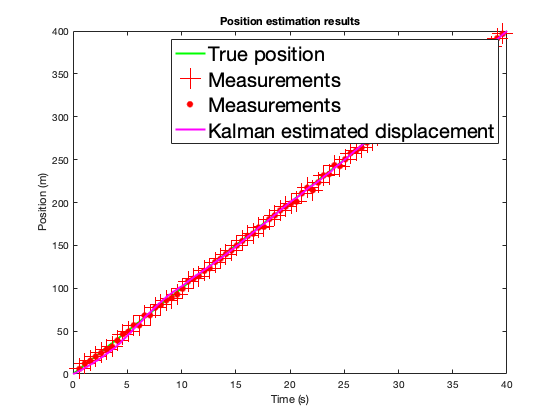

figure;
plot(t,Xtrue,'g','LineWidth',2);
hold on;
plot(find(Z_buffer)*dt,Z_sampled,'r+','MarkerSize',20) % sampled time and measurements
hold on
plot(find(Z_buffer)*dt,Z_sampled,'r.','MarkerSize',20) % sampled time and measurements
plot(t,Xk_buffer(1,:),'m','LineWidth',2);
title('Position estimation results');
xlabel('Time (s)');
ylabel('Position (m)');
le=legend('True position','Measurements','Measurements','Kalman estimated displacement');
set(le,'FontSize',20);
axis([0 Nsamples*dt 0 400])

### Velocity analysis

The instantaneous velocity as derived from 2 consecutive position measurements

InstantaneousVelocity = [0 diff(Z_sampled)/(Laser_Rate*dt)];

The instantaneous velocity as derived from 5 consecutive position measurements

Go to help filter to undertand the coding.

WindowSize = 5;
b = (1/WindowSize)*ones(1,WindowSize);
a = 1;
InstantaneousVelocityRunningAverage = filter(b,a,InstantaneousVelocity);

figure;
plot(t,ones(size(t))*Vtrue,'m');
hold on;
plot(find(Z_buffer)*dt,InstantaneousVelocity,'g');
plot(find(Z_buffer)*dt,InstantaneousVelocityRunningAverage,'c');

plot(t,Xk_buffer(2,:),'k');
title('Velocity estimation results');[]
xlabel('Time (s)');
ylabel('Velocity (m/s)');
le=legend('True velocity','Estimated velocity by raw consecutive samples','Estimated velocity by running average','Estimated velocity by Kalman filter');
set(le,'FontSize',20);
axis([0 Nsamples*dt 0 20])

## Extrapolation 20 samples ahead

We take the last Nlast = 10 samples, and for each of these samples we try to see what would be the estimated position of the train at sample number *Nsamples + SamplesIntoTheFuture* if we took the position and the velocity that was known at that sample.

SamplesIntoTheFuture = 20;
Nlast = 10; % samples

### Theroric


$${x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t$$


TruePositionInTheFuture = Xinitial + (Nsamples + SamplesIntoTheFuture) * Vtrue * dt;

### Averaging

ProjectedPositionByRunningAverage = Xk_buffer(1,(Nsamples+1-Nlast):(Nsamples+1)) + ...% last 11 sample from Kalman
                                    ((SamplesIntoTheFuture+Nlast):-1:SamplesIntoTheFuture) .* dt ... % vector time 
                                    .* InstantaneousVelocityRunningAverage((Nsamples+1-Nlast):(Nsamples+1)); % Avergage velocity

### Kalman ahead

ProjectedPositionByKalmanFilter = Xk_buffer(1,(Nsamples+1-Nlast):(Nsamples+1)) + ...% last 11 sample from Kalman
                                  ((SamplesIntoTheFuture+Nlast):-1:SamplesIntoTheFuture) .* dt ...% vector time 
                                  .* Xk_buffer(2,(Nsamples+1-Nlast):(Nsamples+1));

Plotting Positions

figure;
plot(((Nsamples+1-Nlast):(Nsamples+1))*dt,ones(size(1:11))*TruePositionInTheFuture,'m');
hold on;
plot(((Nsamples+1-Nlast):(Nsamples+1))*dt,ProjectedPositionByRunningAverage,'c');
plot(((Nsamples+1-Nlast):(Nsamples+1))*dt,ProjectedPositionByKalmanFilter,'k');
title(['Extrapolation 20 samples ahead (at t = ' num2str((Nsamples + SamplesIntoTheFuture) * dt) ')']);
xlabel('Time of sample used for extrapolation (s)');
ylabel('Expected position (m)');
legend('True position','Estimated position by running average','Estimated position by Kalman filter');

## The iteration

The loop

Z is the measurement vector. In our case, Z = TrueData + RandomGaussianNoise

function Kalman_out=estimate_update(y_n,n_m,N,Xk_prev,Xinitial)
% y_n; 0 no update; 1 update with innovation
% n_m; avalailability of update

%%%%%%%  The filter structure, see comment above %%%%%%
dt=0.1;
Vtrue=10;
Phi = [1 dt;
       0  1];
sigma_model = 1;
P = [sigma_model^2 0;
     0 sigma_model^2];
Q = [0.01 0;
     0 0.1];
sigma_meas = 2; % 2 m
R = sigma_meas^2;
H=[1 0];
Kalman=[];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k=1:N  
    % Kalman iteration
    Xk=Phi*Xk_prev;
    P1 = Phi*P*Phi' + Q; % Covariance estimated
% checking if update is avalaible
    k_m=mod(k,n_m);
    if (k_m==0) && (y_n>0)
%%%%%%%%% Update is posible %%%%%%%
%     Z = Xtrue(k+1)+sigma_meas*randn; % It is a kind of data measurement simulation
%     Z_buffer(k+1) = Z;
      Xtrue = Xinitial + Vtrue * k*dt     
      Z = Xtrue+sigma_meas*randn; % It is a kind of data measurement simulation
      %Z_buffer(k+1) = Z;
      S = H*P1*H' + R; 
    
      % K is Kalman gain. If K is large, more weight goes to the measurement.
      % If K is low, more weight goes to the model prediction.
      K = P1*H'*inv(S);
      P = P1 - K*H*P1;
    
      Xk = Phi*Xk_prev + K*(Z-H*Phi*Xk_prev);
      Kalman.Xk(:,k+1)=Xk;
      Kalman.Z(1,k+1)=Z;
      Kalman.K(:,k+1)=K;
      Kalman.P(:,:,k+1)=P
      Kalman.P1(:,:,k+1)=P1
  
    end
    % This comes for the estimation
      Kalman.Xk(:,k+1)=Xk;
      Kalman.P1(:,:,k+1)=P1;
      Kalman_out=Kalman;
      % For the next iteration
      Xk_prev = Xk;
end
end

function Zs=Z_n0(Z_buffer)
   Indi=find(Z_buffer);
   for n=1:length(Indi)
   Zs(1,n)=Z_buffer(Indi(n));
   end
end
